# `tall` Arrays for Big Data in MATLAB

## Predict Cost of Taxi Ride in New York City

Analyze data from .csv files containing taxi trip information, separated by month. The data set is available from the [City of New York](https://data.cityofnewyork.us/view/ba8s-jw6u).

TaxiData(small): 12 files (~20MB), 15000 lines in file

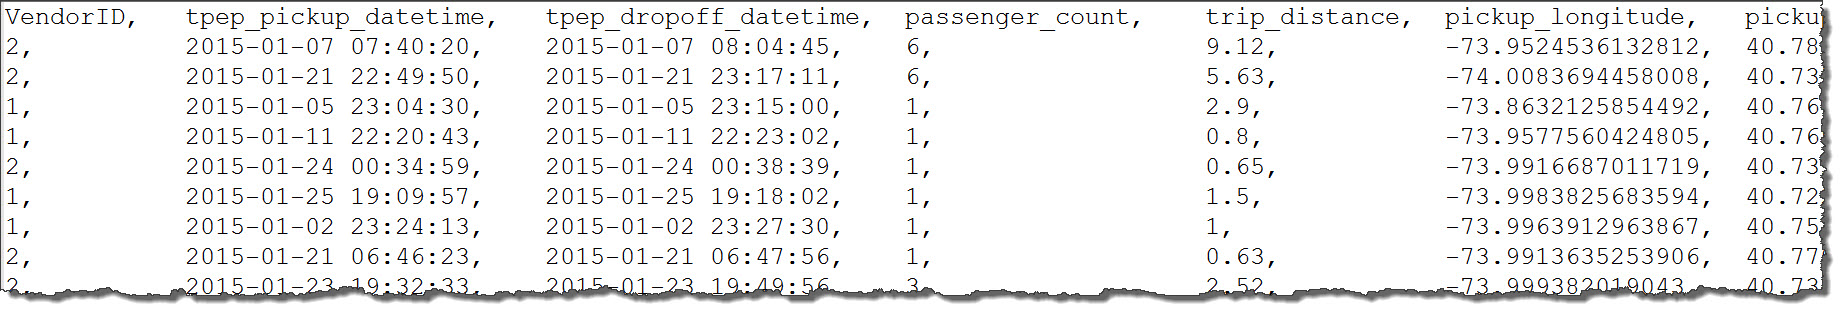

## Set up execution environment

clear; cd('C:\Users\shirang\Documents\Seminars\Expo2017\NYCTaxiTall')
if isempty(gcp('nocreate'))
   parpool local;
end

## Create `datastore` to represent the data

ds = datastore('taxiData\*2015.csv'); % easy access for large collections of data
preview(ds)

Identify data of interest and customize options.

ds.VariableNames(2:3) = {'pickuptime','dropofftime'};
ds.SelectedVariableNames = {'pickuptime','dropofftime','trip_distance',...
    'payment_type','fare_amount'};
preview(ds)

## Create a `tall` array 

tt = tall(ds)

## Determine hour of the day and trip duration

Operations on tall arrays are **deferred and optimized before ****evaluation**

‒Reduces number of operations on the data

‒Reduces number of passes through the data

tt.hr_of_day = hour(tt.pickuptime);
tt.trip_minutes = minutes(tt.dropofftime - tt.pickuptime)

## Execute commands and gather results into workspace

vars = {'trip_distance','fare_amount','trip_minutes','hr_of_day'};
x = tt{:,vars}; % tall double
m = mean(x,'omitnan');
s = std(x,'omitnan');
h = height(tt); % number of observations

`gather` **multiple** variables into the workspace.

[m,s,h] = gather(m,s,h) % optimization to a single pass over the data

## Preprocess data

Convert payment type column to Categorical

tt.payment_type
newCats = {'Credit card', 'Cash', 'No charge', 'Dispute', 'Unknown', 'Voided'};
tt.payment_type = categorical(tt.payment_type,1:6,newCats)

Remove outliers with logical indexing (ignore very short\long rides, and partial or corrupted data)

% idx - a tall logical
idx = tt.trip_minutes <= 1 | ...                   
    tt.trip_minutes >=  60 * 12 | ...            
    tt.trip_distance <= 1 | ...                     
    tt.trip_distance >= 12 * 55 | ...              
    tt.fare_amount <= 0 | ...                       
    tt.fare_amount > 10000 | ...                   
    any(ismissing(tt),2); % remove all lines that contain a missing value                         
tt(idx, :) = []; 

## Explore data

figure
histogram(tt.trip_distance,'BinLimits',[0 30])
title('Trip Distance')

## Work with a subset of the data

Select a subset of data.

ttSub = head(tt,20000);

## Explore data

figure
histogram(ttSub.payment_type)
title('Payment Type')

## Plot Fare Amount vs Trip Distance

A "combination" of Scatter plot and heatmap

binScatterPlot(ttSub.trip_distance,ttSub.fare_amount)
xlabel('Trip Distance (miles)')
ylabel('Fare Amount ($)')

## Create training and validation sets

pt = cvpartition(tt.hr_of_day,'Holdout',0.5);
ttTrain = tt(training(pt),:);
ttValidation = tt(test(pt),:);

## Fit predictive model

`fitlm` creates linear regression model. It takes the last variable as the response variable.

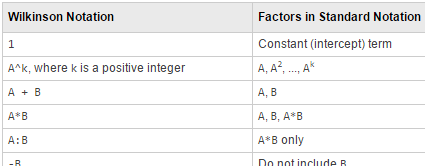

model = fitlm(ttTrain,'fare_amount ~ 1 + hr_of_day + trip_distance*trip_minutes')

Evaluating tall expression using the Parallel Pool 'local':

- Pass 1 of 1: Completed in 4 sec

Evaluation completed in 6 sec


model = 
Compact linear regression model:
    fare_amount ~ 1 + hr_of_day + trip_distance*trip_minutes

Estimated Coefficients:
                                   Estimate        SE         tStat       pValue  
                                  __________    _________    ________    _________

    (Intercept)                       12.685      0.22477      56.435            0
    trip_distance                   -0.17934    0.0045026      -39.83            0
    hr_of_day                     -0.0072228     0.014812    -0.48762      0.62582
    trip_minutes                   -0.018179    0.0028367     -6.4084    1.479e-10
    trip_distance:trip_minutes      0.015438    0.0003876       39.83            0


Number of observations: 78734, Error degrees of freedom: 78729
Root

## Predict and validate

yPred = predict(model,ttValidation);
residuals = yPred - ttValidation.trip_minutes;
figure
histogram(residuals,'Normalization','pdf','BinLimits',[-50 50])

Evaluating tall expression using the Parallel Pool 'local':

- Pass 1 of 2: Completed in 6 sec

- Pass 2 of 2: Completed in 4 sec

Evaluation completed in 12 sec


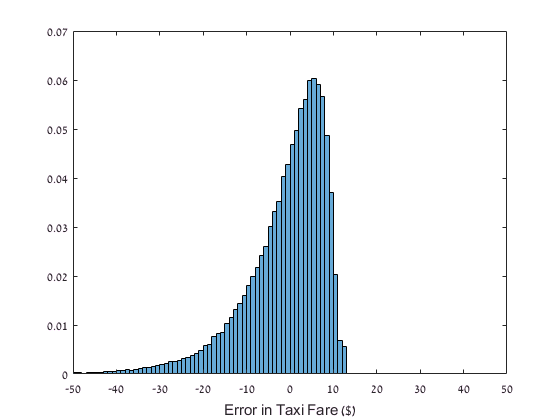

xlabel('Error in Taxi Fare ($)')